clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

DHparameter=[0 pi/2 40 0;
             120 0 0 13*pi/30+pi/2;
             194 -pi/2 0 -23*pi/30+pi/2;
             0 0 176 0;
             0 pi/2 0 pi/2;
             0 0 0 0;
             50 0 0 pi]

DHparameter =          0    1.5708   40.0000         0
  120.0000         0         0    2.9322
  194.0000   -1.5708         0   -0.8378
         0         0  176.0000         0
         0    1.5708         0    1.5708
         0         0         0         0
   50.0000         0         0    3.1416


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",7,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
% joint1.PositionLimits = [0 2*pi];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];

body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');
joint2.HomePosition = 13*pi/30+pi/2;
% joint2.PositionLimits = [0 23*pi/33];
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];

body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;
joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-pi/3 pi/3]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];

body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;
% joint4.PositionLimits = [0 2*pi];

body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');
% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [-pi/4 pi/4];
body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [-pi/4 pi/4];
body6.Mass = 10;

body7 = rigidBody('Body7');
joint7 = rigidBodyJoint('Joint7','prismatic');
% joint7.PositionLimits = [0 75];
body7.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;
setFixedTransform(joint7,DHparameter(7,:),"dh");
body7.Joint = joint7;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');
addBody(dental,body7,'Body6');


showdetails(dental)

--------------------
Robot: (7 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7     prismatic            Body6(6)   
--------------------


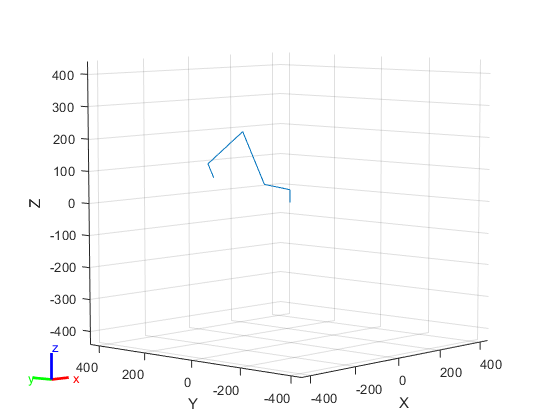


figure
show(dental,"Collisions","on","Visuals","off");
view([-48 6])

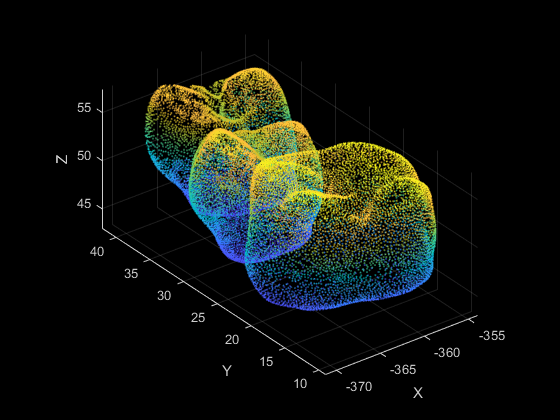

% Read and plot complete denture
stlData = stlread('1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
% figure
% pcshow(ptCloud)

% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
% pcshow(ptCloudB.Location);

% Import and plot final model individually
stlData_fin = stlread("1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
% pcshow(ptCloud_fin);

% Three teeth in the denture
% figure
% pcshow(ptCloud);
% hold on;
% pcshow(ptCloudB.Location,'r');
% legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
% xlabel('X'); ylabel('Y'); zlabel('Z');
% hold off;

% Final tooth inside the considered tooth
% figure
% pcshow(ptCloudB.Location);
% hold on;
% pcshow(ptCloud_fin);
% hold off;

%Transformation (shrink and move)
Sx = 1.3;
Sy = 1.3;
Sz = 1.3;

tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = 50;
trans = 1000*[-0.3 -0.01 zCoord/1000];
rigid_tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,rigid_tform);
ptCloud_fin = pctransform(ptCloud_fin,rigid_tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

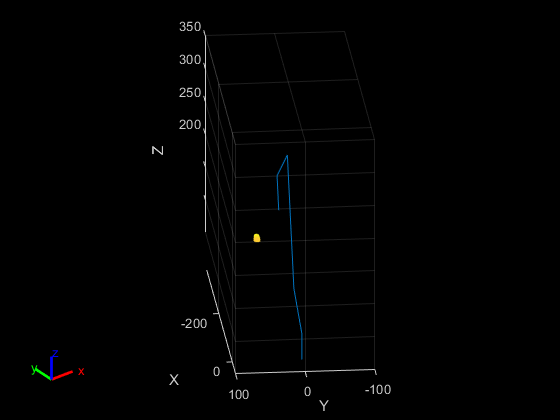

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')
hold on
show(dental);
axis([-400 50 -100 100 0 350])

stlData = stlread('Single_Back_tooth.STL');
points = stlData.Points;
backTooth = pointCloud(points);



stlData = stlread('Single_front_tooth.STL');
points = stlData.Points;
frontTooth = pointCloud(points);

frontTooth = pctransform(frontTooth,tform);
backTooth = pctransform(backTooth,tform);

frontTooth = pctransform(frontTooth,rigid_tform);
backTooth = pctransform(backTooth,rigid_tform);

% robot = loadrobot("kukaIiwa14","DataFormat","row");
robot = dental;
figure

tooth = collisionMesh(ptCloud_fin.Location);
front = collisionMesh(frontTooth.Location);
back = collisionMesh(backTooth.Location);

jawLow = collisionBox(50,50,2);
jawLow.Pose(1:3,end) = 1000*[-0.375 0.025 52/1000];

jawUp = collisionBox(50,50,20);
jawUp.Pose(1:3,end) = 1000*[-0.375 0.025 64/1000];

env = {tooth front back jawLow jawUp}

env = 1×5 cell array
    {1×1 collisionMesh}    {1×1 collisionMesh}    {1×1 collisionMesh}    {1×1 collisionBox}    {1×1 collisionBox}


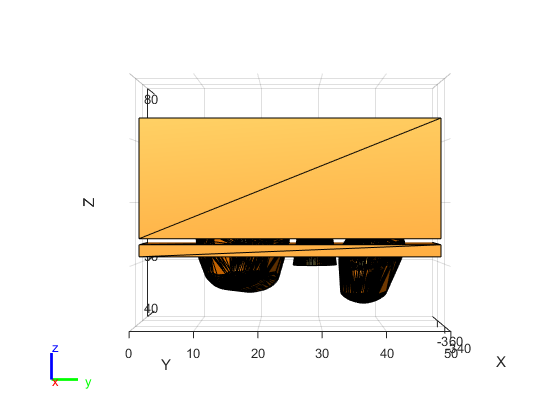


show(robot);
hold on
showEnv(env)
axis([-375 -325 0 50 40 80])

view([90 0])

GET CONTOURS

figure
allPoints = {};
r = 0.5

r = 0.5000

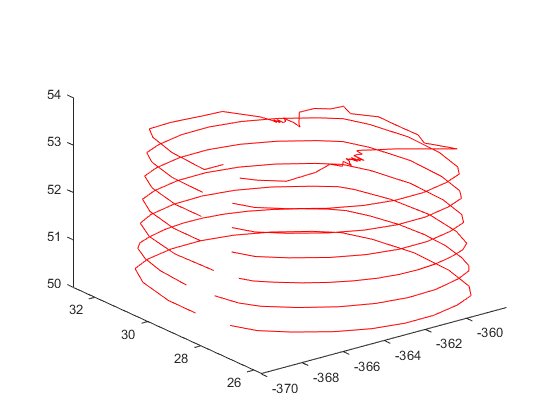

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],12);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.01);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

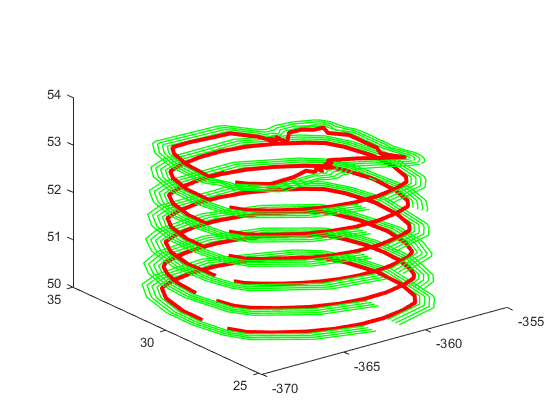

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.2*j);
        polyout.Vertices = downsample(polyout.Vertices,12);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

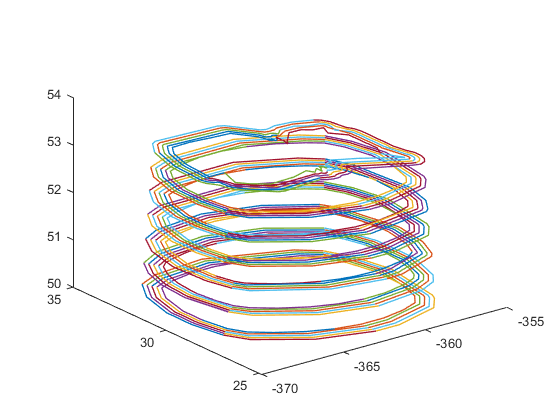

curve1 = allPoints{5,1};
appendAllPoints = [];
figure

for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

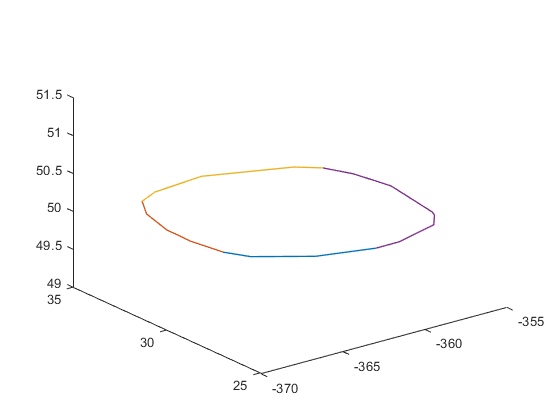

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back

## `Splitting Geometry and Forming into Trajectory`

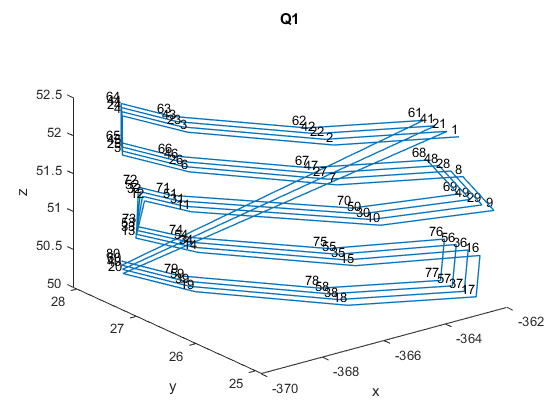

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);

q1_traj_arr_fixed = [];
for i = 1:80
    q1_traj_arr_fixed(i,:) = q1_traj_arr(i,:);
end

q2_traj_arr_fixed = [];
for i = 1:100  
    q2_traj_arr_fixed(i,:) = q2_traj_arr(i,:);
end

q3_traj_arr_fixed = [];
for i = 1:100
    q3_traj_arr_fixed(i,:) = q3_traj_arr(i,:);
end

q4_traj_arr_fixed = [];
for i = 1:156
    q4_traj_arr_fixed(i,:) = q4_traj_arr(i,:);
end

save fixed_contour.mat q1_traj_arr_fixed q2_traj_arr_fixed q3_traj_arr_fixed q4_traj_arr_fixed

figure
plotQuarter(q1_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
title('Q1')

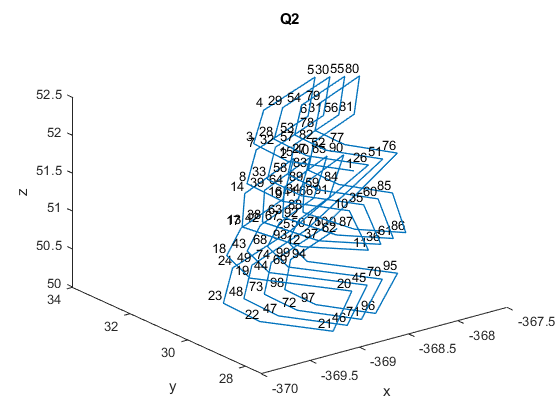


plotQuarter(q2_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
title('Q2')

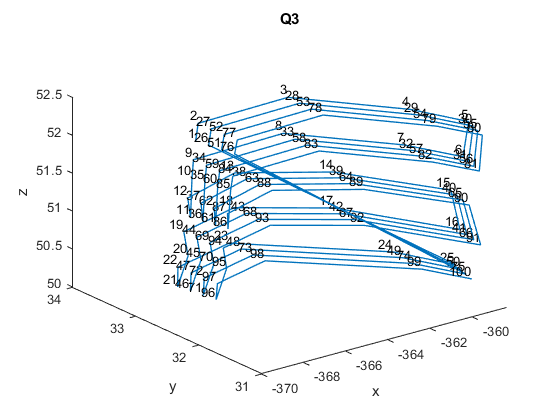


plotQuarter(q3_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
title('Q3')

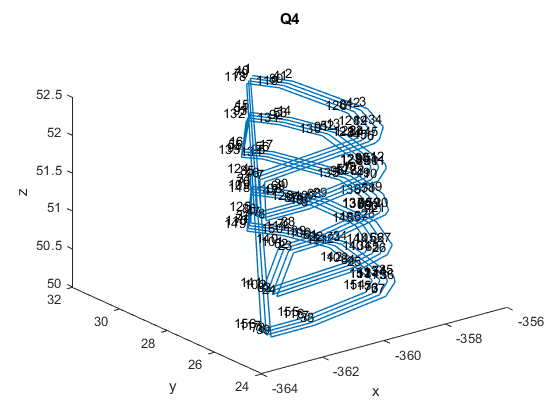


plotQuarter(q4_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
title('Q4')
hold off

% hold on
% pcshow(ptCloud_3t)
% figure
% plotQuarter(q1_traj_arr);
% plotQuarter(q2_traj_arr);
% plotQuarter(q3_traj_arr);
% plotQuarter(q4_traj_arr);

% getTransform(robot,)

collisionObj = collisionCylinder(0.2,4);
collisionObj.Pose = [0 0 1 0;
                     0 1 0 0;
                     -1 0 0 0;
                     0 0 0 1];
clearCollision(robot.Bodies{7})
addCollision(robot.Bodies{7},collisionObj)

env2 = {front back}

env2 = 1×2 cell array
    {1×1 collisionMesh}    {1×1 collisionMesh}


rrt = manipulatorRRT(robot,env2);
rrt.MaxConnectionDistance = 0.001

rrt =   manipulatorRRT with properties:

      MaxConnectionDistance: 1.0000e-03
              MaxIterations: 10000
     EnableConnectHeuristic: 1
         ValidationDistance: 0.0100
    WorkspaceGoalRegionBias: 0.5000


% rrt.MaxIterations = 50;


% startPoint = allPoints{2,1}(3,:)
% endPoint = allPoints{2,1}(4,:)

% ik = inverseKinematics('RigidBodyTree',robot);
% startVector = trvec2tform(startPoint);
% endVector = trvec2tform(endPoint);
% weights = [0 0 0 1 1 1];
% [qStart, solinfoStart] = ik("Body7",startVector,weights,robot.homeConfiguration);
% [qEnd, solinfoEnd] = ik("Body7",endVector,weights,robot.homeConfiguration);

% [qStart, qEnd] = getPoints(startPoint,endPoint,robot)

% rng(0)
% path = plan(rrt,qStart',qEnd');

% interpPath = interpolate(rrt,path);
close all;
figure
fps = 60;
r = rateControl(fps);

set(gcf,'Visible','on')

traj = [];

% innermost is 1, outermost is 5
contourNum = 5;

% this iterates thorugh all contours vertically (bottom to top)
% for k=1:7
%     for i=1:length(allPoints{contourNum,k})
%         startPoint = allPoints{contourNum,k}(i,:);
%         endPoint = allPoints{contourNum,k}(i,:);
%         [qStart, qEnd] = getPoints(startPoint,endPoint,robot);
%         getTransform(robot,qEnd,'Body6')
%         rng(0)
%         path = plan(rrt,qStart',qEnd');
%         interpPath = interpolate(rrt,path);
%         
%         h = animatedline;
%         
%         for j = 1:5:size(interpPath,1)   
%             show(robot,interpPath(j,:)','PreservePlot',false,"Collisions","on");
%             drawnow
%             waitfor(r);
%             hold on;
%             showEnv(env2)
%             show(tooth)
%             axis([-375 -325 0 50 40 80])
%         %     view([1 1 1])
%             isColliding = checkCollision(robot,interpPath(j,:)',env2);
%             if(any(isColliding))
%                 title("Collision with neighbouring teeth")
%             end
%             
%             ee = getTransform(robot,interpPath(j,:)',"Body7")
%             traj = [traj;ee(1:3,end)'];
% 
% %             addpoints(h,ee(1,end),ee(2,end),ee(3,end));
% %             scatter3(ee(1,end),ee(2,end),ee(3,end),'+',"LineWidth",1,"MarkerEdgeColor",'r');
%             
%         
%         end
% %         scatter3(startPoint(1),startPoint(2),startPoint(3),'o',"LineWidth",5)
% %         scatter3(endPoint(1),endPoint(2),endPoint(3),'o',"LineWidth",5)
%         
%         
%     end
% end
% 
% plot3(traj(:,1),traj(:,2),traj(:,3),"Color",[0 0 1],"Marker","*")

q1_to_Home = quarterToHome('q1',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);
home_to_q3 = homeToQuarter('q3',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);
q3_to_Home = quarterToHome('q3',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);
home_to_q2 = homeToQuarter('q2',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);
q2_to_Home = quarterToHome('q2',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);
home_to_q4 = homeToQuarter('q4',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);
q4_to_Home = quarterToHome('q4',ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed);


points = [q1_traj_arr_fixed; 
          q1_to_Home;
          home_to_q3;
          q3_traj_arr_fixed;
          q3_to_Home;
          home_to_q2;
          q2_traj_arr_fixed; 
          q2_to_Home;
          home_to_q4;
          q4_traj_arr_fixed;
          q4_to_Home];
            
robotConfig = []


robotConfig =

     []



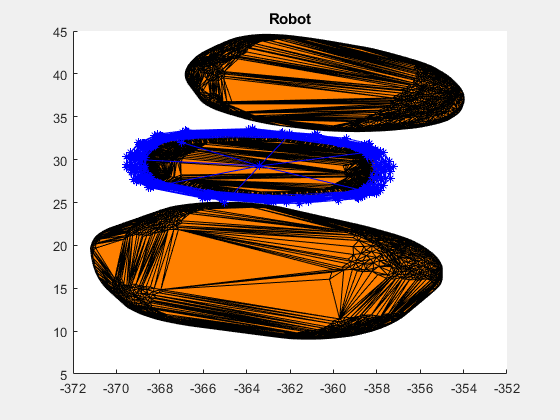


for i=1:length(points)
    startPoint = points(i,:);
    endPoint = points(i,:);
    [qStart, qEnd] = getPoints(startPoint,endPoint,robot);
    getTransform(robot,qEnd,'Body6');
    rng(0)
    path = plan(rrt,qStart',qEnd');
    interpPath = interpolate(rrt,path);
    
    robotConfig = [robotConfig; interpPath];
    
    for j = 1:5:size(interpPath,1)   
%         show(robot,interpPath(j,:)','PreservePlot',false,"Collisions","on");
%         drawnow
%         waitfor(r);
%         hold on;
%         showEnv(env2)
%         show(tooth)
%         axis([-375 -325 0 50 40 80])
    %     view([1 1 1])
        isColliding = checkCollision(robot,interpPath(j,:)',env2);
        if(any(isColliding))
            title("Collision with neighbouring teeth")
            disp("Collision")
        end
        
        ee = getTransform(robot,interpPath(j,:)',"Body7");
        traj = [traj;ee(1:3,end)'];

%             addpoints(h,ee(1,end),ee(2,end),ee(3,end));
%             scatter3(ee(1,end),ee(2,end),ee(3,end),'+',"LineWidth",1,"MarkerEdgeColor",'r');
        
    
    end
%         scatter3(startPoint(1),startPoint(2),startPoint(3),'o',"LineWidth",5)
%         scatter3(endPoint(1),endPoint(2),endPoint(3),'o',"LineWidth",5)
    
    
end

hold on;
showEnv(env2)
show(tooth)
plot3(traj(:,1),traj(:,2),traj(:,3),"Color",[0 0 1],"Marker","*")


% for i = 1:size(interpPath,1)   
%     show(robot,interpPath(i,:)','PreservePlot',true,"Collisions","on");
%     drawnow
%     waitfor(r);
%     hold on;
%     showEnv(env2)
%     axis([-375 -325 0 50 40 80])
% %     view([1 1 1])
%     isColliding = checkCollision(robot,interpPath(i,:)',env)
%     ee = getTransform(robot,interpPath(i,:)',"Body7");
%     scatter3(ee(1,end),ee(2,end),ee(3,end),'+',"LineWidth",1,"MarkerEdgeColor",'r');
% %     pause(0.05)
% end
% scatter3(startPoint(1),startPoint(2),startPoint(3),'o',"LineWidth",5)
% scatter3(endPoint(1),endPoint(2),endPoint(3),'o',"LineWidth",5)

title("Robot")
hold off

a = getTransform(robot,interpPath(end,:)',"Body7")

a =     0.2216    0.9738   -0.0505 -363.4076
    0.0220   -0.0568   -0.9981   29.2574
   -0.9749    0.2200   -0.0340   58.0000
         0         0         0    1.0000


size(robotConfig)

ans =    511     7


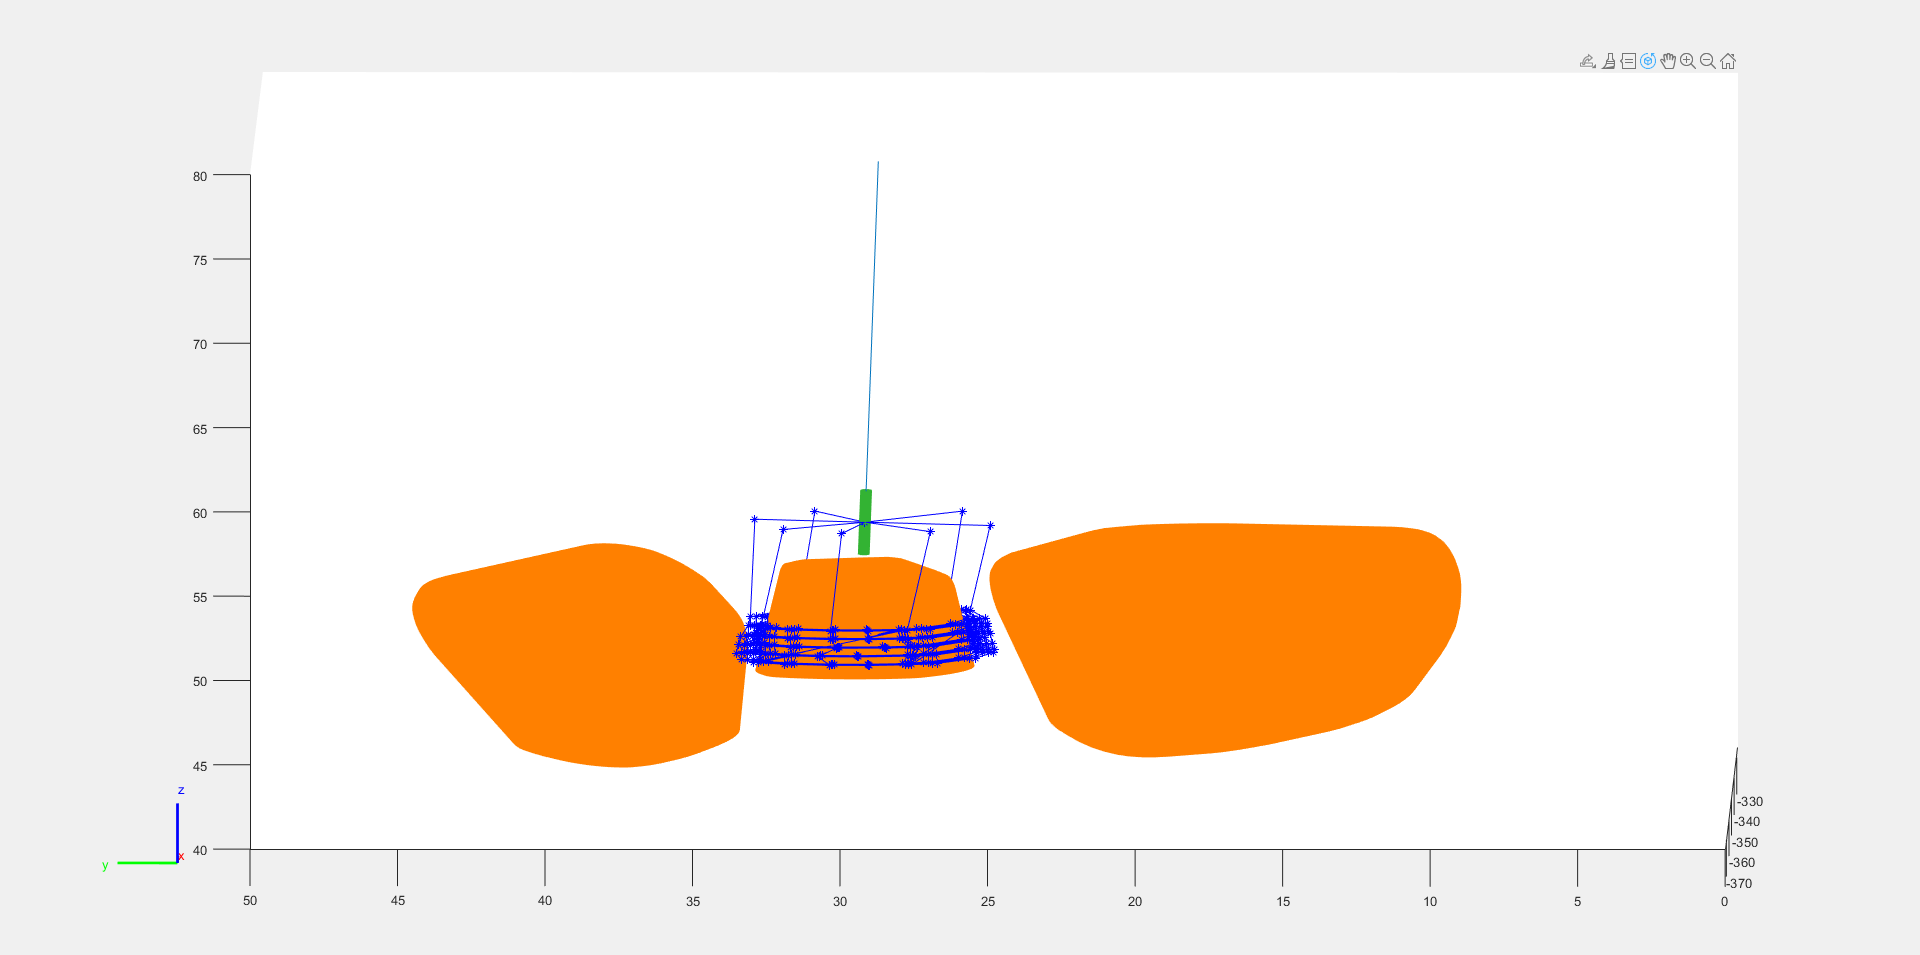

figure
set(gcf,'Visible','on')
plot3(traj(:,1),traj(:,2),traj(:,3),"Color",[0 0 1],"Marker","*"); hold on;
showEnv(env2);
show(tooth);
for i=1:length(robotConfig)
    show(robot,robotConfig(i,:)',"PreservePlot",false,"Collisions","on");
    drawnow
    axis([-375 -325 0 50 40 80])
    waitfor(r);
    pause(0.05)
end

## `Helper Functions`

function [qStart, qEnd] = getPoints(startPoint, endPoint,robot)
 
    ik = inverseKinematics('RigidBodyTree',robot);
    startVector = trvec2tform(startPoint);
    endVector = trvec2tform(endPoint);
    weights = [0 0 0 1 1 1];
    [qStart, solinfoStart] = ik("Body7",startVector,weights,robot.homeConfiguration);
    [qEnd, solinfoEnd] = ik("Body7",endVector,weights,robot.homeConfiguration);
end

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
%     curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body7','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 20;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis(1000*[-0.4 0.5 -0.3 0.3 -0.2 0.2])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
%         show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
        line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
%         plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = 58;
    homeConfig = [x y z;
                  x y z;
                  x y z;
                  x y z;
                  x y z;
                  x y z];
end

### `Check if path in collision or not`

function isTrajectoryInCollision = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
%     rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
end

function showEnv(env)
    for i=1:length(env)
        show(env{i}); hold on;
    end
end

### `Quarter to Home`

function quarterToHome = quarterToHome(quarter, ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed)
    homeConfig = findHomeConfig(ptCloud_fin);
    if quarter == 'q1'
        wayPoints = [q1_traj_arr_fixed(end,:);
                     q1_traj_arr_fixed(18,:);
                     q1_traj_arr_fixed(10,:);
                     q1_traj_arr_fixed(7,:);
                     q1_traj_arr_fixed(2,:);
                     [-365 25 58];
                     homeConfig];
    elseif quarter == 'q2'
        wayPoints = [q2_traj_arr_fixed(end,:);
                     q2_traj_arr_fixed(23,:);
                     q2_traj_arr_fixed(18,:);
                     q2_traj_arr_fixed(13,:);
                     q2_traj_arr_fixed(8,:);
                     q2_traj_arr_fixed(3,:);
                     [-369 30 58];
                     homeConfig];
    elseif quarter == 'q3'
        wayPoints = [q3_traj_arr_fixed(end,:);
                     q3_traj_arr_fixed(23,:);
                     q3_traj_arr_fixed(18,:);
                     q3_traj_arr_fixed(13,:);
                     q3_traj_arr_fixed(8,:);
                     q3_traj_arr_fixed(3,:);
                     [-362 33 58];
                     homeConfig];
        
    elseif quarter == 'q4'
        wayPoints = [q4_traj_arr_fixed(end,:);
                     q4_traj_arr_fixed(37,:);
                     q4_traj_arr_fixed(26,:);
                     q4_traj_arr_fixed(21,:);
                     q4_traj_arr_fixed(11,:);
                     q4_traj_arr_fixed(4,:);
                     [-358 26 58];
                     homeConfig];
    end
    quarterToHome = wayPoints;
end

### `Home to Quarters`

function homeToQuarter = homeToQuarter(quarter, ptCloud_fin,q1_traj_arr_fixed,q2_traj_arr_fixed,q3_traj_arr_fixed,q4_traj_arr_fixed)
    homeConfig = findHomeConfig(ptCloud_fin);
    if quarter == 'q1'
        wayPoints = [homeConfig;
                     [-362 25 58];
                     q1_traj_arr_fixed(1,:)];
    
    elseif quarter == 'q2'
        wayPoints = [homeConfig;
                     [-368 27 58];
                     q2_traj_arr_fixed(1,:)];
    
    elseif quarter == 'q3'
        wayPoints = [homeConfig;
                     [-367 32 58];
                     q3_traj_arr_fixed(1,:)];
        
    elseif quarter == 'q4'
        wayPoints = [homeConfig;
                     [-358 31 58];
                     q4_traj_arr_fixed(1,:)];
    end
    homeToQuarter = wayPoints;
end